# Momentum-based Estimator

The goal of this work is to implement  the momentum-based estimator of order *r *to estimate the external disturbances acting on the UAV during the flight. Within the file  ***ws_homework_3_2025.mat***  are provided: the values of a flight with a quadrotor with the commanded thrust (thrust) and torques (tau), the measured linear velocity (linear_vel), attitude expressed as Euler angles (attitude) and the time derivative of such angles (attitude_vel). The employed quadrotor has a supposed mass of 1.5 kg and an inertia matrix referred to the body frame equal to diag([1.2416 1.2416 2*1.2416]). 						

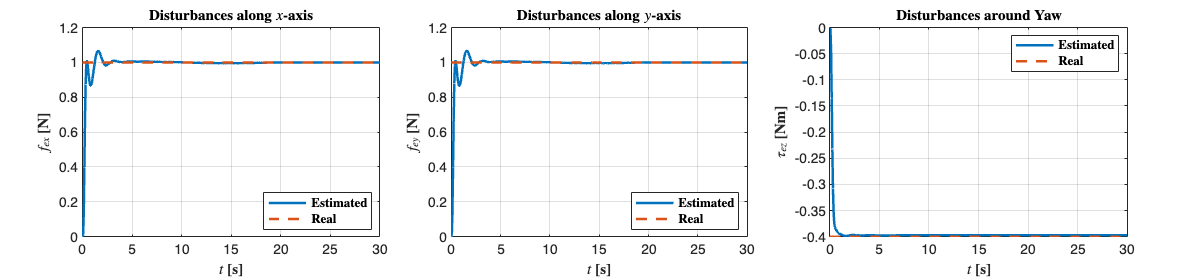

% User input for estimator order
r = input('Enter the order of the estimator (must be r>=1): ');
while r < 1
    disp('Error: The order must be at least 1.');
    r = input('Enter the order of the estimator (must be r>=1): ');
end

% Load quadrotor data  
data = load('ws_homework_3_2025.mat');
eta = data.attitude.signals.values;
eta_dot = data.attitude_vel.signals.values;
p_b_dot = data.linear_vel.signals.values;
tau_b = data.tau.signals.values;
u_T = data.thrust.signals.values;
t = data.linear_vel.time;

% Model parameters
m = 1.5; % kg
g = 9.81; % m/s^2
e_3 = [0; 0; 1];
I_wrtb = diag([1.2416, 1.2416, 2*1.2416]);

% Estimator parameters
Ts = 0.001; % Sampling time
k0 = 20;    % Pole location

% Transfer Function 
s = tf('s');
G = k0^r/(s + k0)^r; % pole = k0
c = cell2mat(G.Denominator);
c = c(2:end);

% Compute K coefficients using Hurwitz polynomial coefficients
K = quaternion_utils.computeKCoefficients(r, c);
   

% Initialization
q = zeros(6, length(t)); 
gamma = zeros(6, length(t), r);
extWrench_hat = zeros(6, length(t)); 

% Main estimation loop
for i = 1:size(t,1)-1
    % Get rotation matrix from Euler angles
    Rb = quaternion_utils.RbMatrix(eta(i,1), eta(i,2), eta(i,3));
    
    % Get angular velocity transformation matrices
    [Q, Qdot] = quaternion_utils.EulerToBodyAngularVelocityMatrix(eta(i,1), eta(i,2), eta_dot(i,1), eta_dot(i,2));
    
    % Get Coriolis matrix
    C = quaternion_utils.CMatrix(eta_dot(i,:), Q, Qdot, I_wrtb);
    
    % Compute mass matrix
    M = Q' * I_wrtb * Q;
    
    % Update generalized momentum
    q(:,i+1) = [m*eye(3), zeros(3,3); zeros(3,3), M] * [p_b_dot(i+1,:)'; eta_dot(i+1,:)'];
    
    % Update gamma (order r estimator)
    gamma(:,i+1,1) = gamma(:,i,1) + K(1)*(q(:,i+1) - q(:,i) - Ts*extWrench_hat(:,i) - Ts*[(m*g*e_3 - u_T(i)*Rb*e_3); C'*eta_dot(i,:)' + Q'*tau_b(i,:)']);
    
    for j = 2:r        
        gamma(:,i+1,j) = gamma(:,i,j) + K(j)*Ts*(-extWrench_hat(:,i) + gamma(:,i,j-1)); 
    end
    
    % Update disturbance wrench estimate
    extWrench_hat(:,i+1) = gamma(:,i+1,r);
end

% Disturbances applied during the flight (for comparison)
f_x = 1; % N
f_y = f_x; % N
tau_z = -0.4; % Nm

%% Plot settings
fontSize = 11;
titleSize = 12;
legendSize = 10;
lineWidth = 2;
colors = [0 0.4470 0.7410;  % Blue
          0.8500 0.3250 0.0980]; % Orange

%% Create figure
figure('Name', ['Estimated vs Real Disturbances (Order r=', num2str(r), ')'], 'Units', 'normalized', 'Position', [0.1 0.1 0.8 0.8]);

%% Create and configure subplots with proper positioning
% First create all three plots to have their handles
subplot(1,3,1); % X-axis plot
subplot(1,3,2); % Y-axis plot
subplot(1,3,3); % Yaw plot

% Get the axes handles in the correct order
h = findobj(gcf, 'type', 'axes');
ax1 = h(3); % X-axis plot
ax2 = h(2); % Y-axis plot
ax3 = h(1); % Yaw plot

% Position each subplot with enough spacing to avoid ylabel overlap
set(ax1, 'Position', [0.07, 0.15, 0.25, 0.75]);
set(ax2, 'Position', [0.38, 0.15, 0.25, 0.75]);
set(ax3, 'Position', [0.70, 0.15, 0.25, 0.75]);

%% X-Axis Force
axes(ax1);
plot(t, extWrench_hat(1,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
hold on;
plot(t, f_x.*ones(size(t)), 'Color', colors(2,:), 'LineWidth', lineWidth, 'LineStyle', '--');
grid on;
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$f_{ex}$ [N]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'\textbf{Estimated}', '\textbf{Real}'}, 'FontSize', legendSize, 'Interpreter', 'latex', ...
       'Location', 'southeast', 'NumColumns', 1);
title('\textbf{Disturbances along $x$-axis}', 'FontSize', titleSize, 'Interpreter', 'latex');
set(gca, 'FontSize', fontSize);
%ylim([0 1.2]); % Match the y-axis limits from second figure

%% Y-Axis Force
axes(ax2);
plot(t, extWrench_hat(2,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
hold on;
plot(t, f_y.*ones(size(t)), 'Color', colors(2,:), 'LineWidth', lineWidth, 'LineStyle', '--');
grid on;
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$f_{ey}$ [N]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'\textbf{Estimated}', '\textbf{Real}'}, 'FontSize', legendSize, 'Interpreter', 'latex', ...
       'Location', 'southeast', 'NumColumns', 1);
title('\textbf{Disturbances along $y$-axis}', 'FontSize', titleSize, 'Interpreter', 'latex');
set(gca, 'FontSize', fontSize);
%ylim([0 1.2]); % Match the y-axis limits from second figure

%% Yaw-Axis Torque (τ_z)
axes(ax3);
plot(t, extWrench_hat(6,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
hold on;
plot(t, tau_z.*ones(size(t)), 'Color', colors(2,:), 'LineWidth', lineWidth, 'LineStyle', '--');
grid on;
xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
ylabel('\textbf{$\tau_{ez}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex');
legend({'\textbf{Estimated}', '\textbf{Real}'}, 'FontSize', legendSize, 'Interpreter', 'latex', ...
       'Location', 'northeast', 'NumColumns', 1); % Changed to northeast to avoid overlap
title('\textbf{Disturbances around Yaw}', 'FontSize', titleSize, 'Interpreter', 'latex');
set(gca, 'FontSize', fontSize);
%ylim([-0.4 0]); % Match the y-axis limits from second figure

% Move the ylabel of the third subplot further left to avoid overlap
yh = get(ax3, 'YLabel');
set(yh, 'Units', 'normalized');
pos = get(yh, 'Position');
set(yh, 'Position', [pos(1)-0.02, pos(2), pos(3)]);

%% Set figure size after all plots are created
set(gcf, 'Units', 'normalized');
set(gcf, 'Position', [0.1 0.1 0.8 0.3]); % Make figure more rectangular like the second image

% Save figure
saveas(gcf, ['disturbance_estimates_r', num2str(r), '.eps'], 'epsc');


% %% Z-Axis Force
% subplot(2,3,3);
% plot(t, extWrench_hat(3,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
% grid on;
% xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% ylabel('\textbf{$f_{ez}$ [N]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% legend({'\textbf{Estimated}'}, 'FontSize', legendSize, 'Interpreter', 'latex');
% title('\textbf{Disturbances along $z$-axis}', 'FontSize', titleSize, 'Interpreter', 'latex');
% set(gca, 'FontSize', fontSize);
% 

% Roll-Axis Torque (τ_x)
% subplot(2,3,5);
% plot(t, extWrench_hat(4,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
% grid on;
% xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% ylabel('\textbf{$\tau_{ex}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% legend({'\textbf{Estimated}'}, 'FontSize', legendSize, 'Interpreter', 'latex');
% title('\textbf{Disturbances around roll}', 'FontSize', titleSize, 'Interpreter', 'latex');
% set(gca, 'FontSize', fontSize);

% %% Pitch-Axis Torque (τ_y)
% subplot(2,3,5);
% plot(t, extWrench_hat(5,:), 'Color', colors(1,:), 'LineWidth', lineWidth);
% grid on;
% xlabel('\textbf{$t$ [s]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% ylabel('\textbf{$\tau_{ey}$ [Nm]}', 'FontSize', fontSize, 'Interpreter', 'latex');
% legend({'\textbf{Estimated}'}, 'FontSize', legendSize, 'Interpreter', 'latex');
% title('\textbf{Disturbances around pitch}', 'FontSize', titleSize, 'Interpreter', 'latex');
% set(gca, 'FontSize', fontSize);
% 

** Real mass of the UAV** computation from the estimated disturbance along the *z-*axis:							 

% Calculate estimated mass from z-axis disturbance
uz = u_T(end)*Rb*e_3;
uz = uz(3);
m_tilde = extWrench_hat(3,end)/g;
estimated_mass = m + m_tilde;

% Display results
disp(['Estimated mass: ', num2str(estimated_mass), ' kg']);

Estimated mass: 1.25 kg
